# Sample 9-3

## 離散ウェーブレット変換

重複変換のフィルタバンク実装

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete wavelet transform

Filter bank implementation of lapped transforms

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

## 入力信号の生成

(Generation of input)

% Input signal
u = [ 0 3 1 3 1 5 3 0 ]; % Set to even length

### 並列フィルタバンク実装

(Parallel filter bank implementation)

分析フィルタバンクをデシメータで、合成フィルタバンクをインタポレータで実装

% # of channels
nChs = 2;

% Analysis filters
h0 = [   (1-sqrt(3)) (3-sqrt(3))  (3+sqrt(3)) (1+sqrt(3)) ]/(4*sqrt(2));
h1 = [  -(1+sqrt(3)) (3+sqrt(3)) -(3-sqrt(3)) (1-sqrt(3)) ]/(4*sqrt(2));

% Synthesis filters
f0 = fliplr(h0);
f1 = fliplr(h1);

% Or the function WFILTERS from Wavelet Toolbox as
% [h0,h1,f0,f1] = wfilters('db2');

% Analysis process
s0 = downsample(conv(h0,u),nChs);
s1 = downsample(conv(h1,u),nChs);

% Synthesis process
v0 = conv(f0,upsample(s0,nChs));
v1 = conv(f1,upsample(s1,nChs));
v = v0 + v1;

## 信号表示

(Signal display)

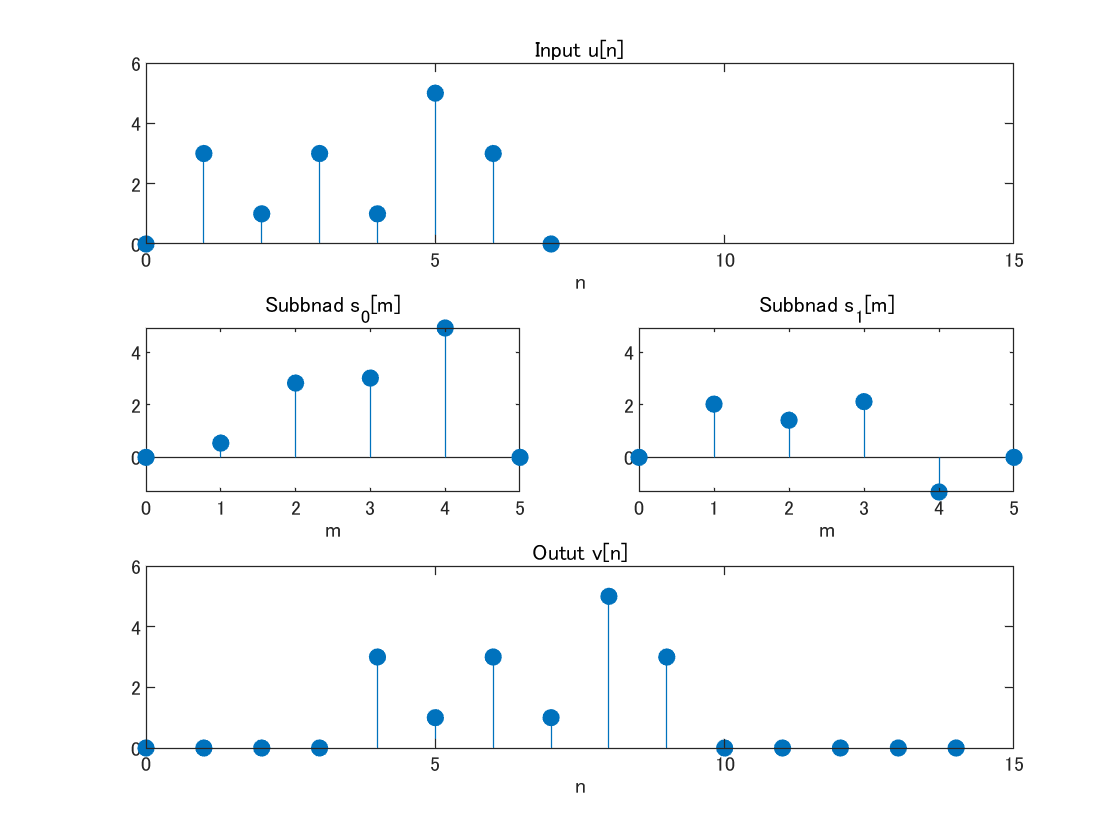

figure(1)
% Input
subplot(3,2,[1,2])
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

% Subband 0
subplot(3,2,3)
stem(0:length(s0)-1,s0,'filled')
title('Subbnad s_0[m]')
xlabel('m')
ax = gca;
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Subband 1
subplot(3,2,4)
stem(0:length(s1)-1,s1,'filled')
title('Subbnad s_1[m]')
xlabel('m')
ax = gca;
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Output
subplot(3,2,[5,6])
stem(0:length(v)-1,v,'filled')
title('Outut v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

### インパルス応答（局所基底ベクトル）

(Impluse responses of synthesis filters; local basis vectors)

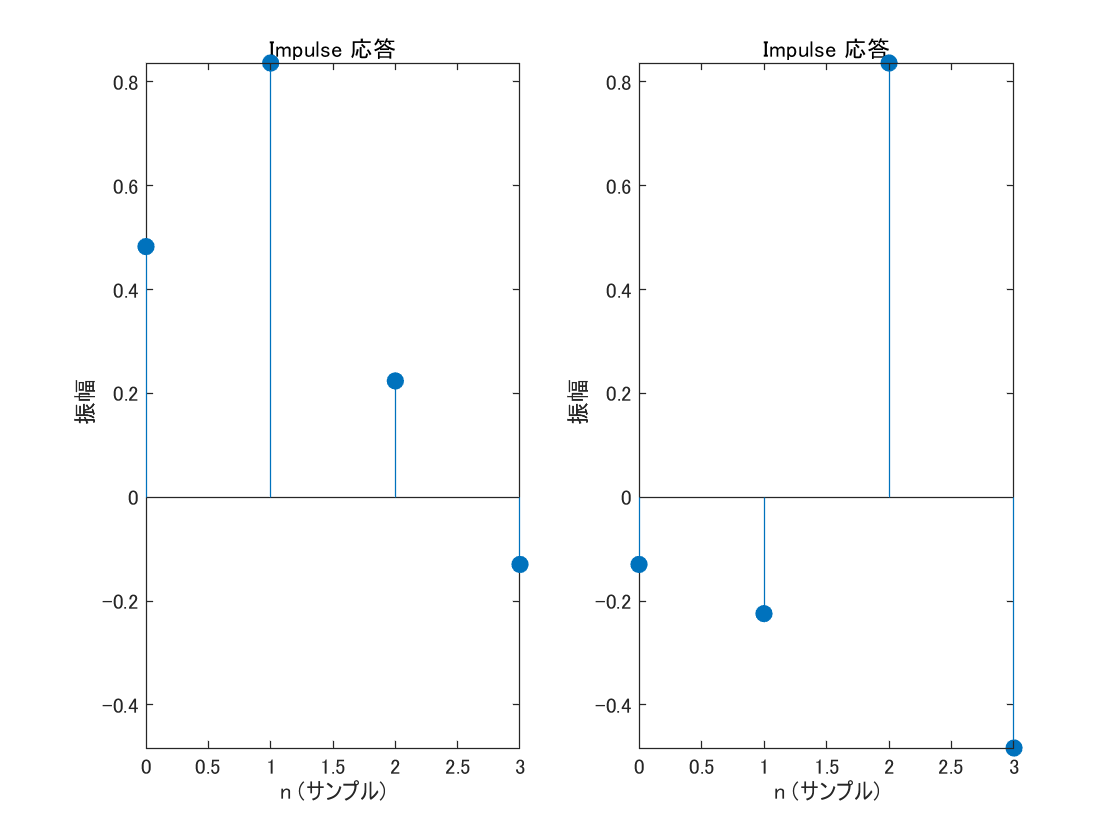

figure(2)
% Low-pass filter
subplot(1,2,1)
impz(f0)
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

% High-pass filter
subplot(1,2,2)
impz(f1)
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

### 周波数応答

(Frequency responses)

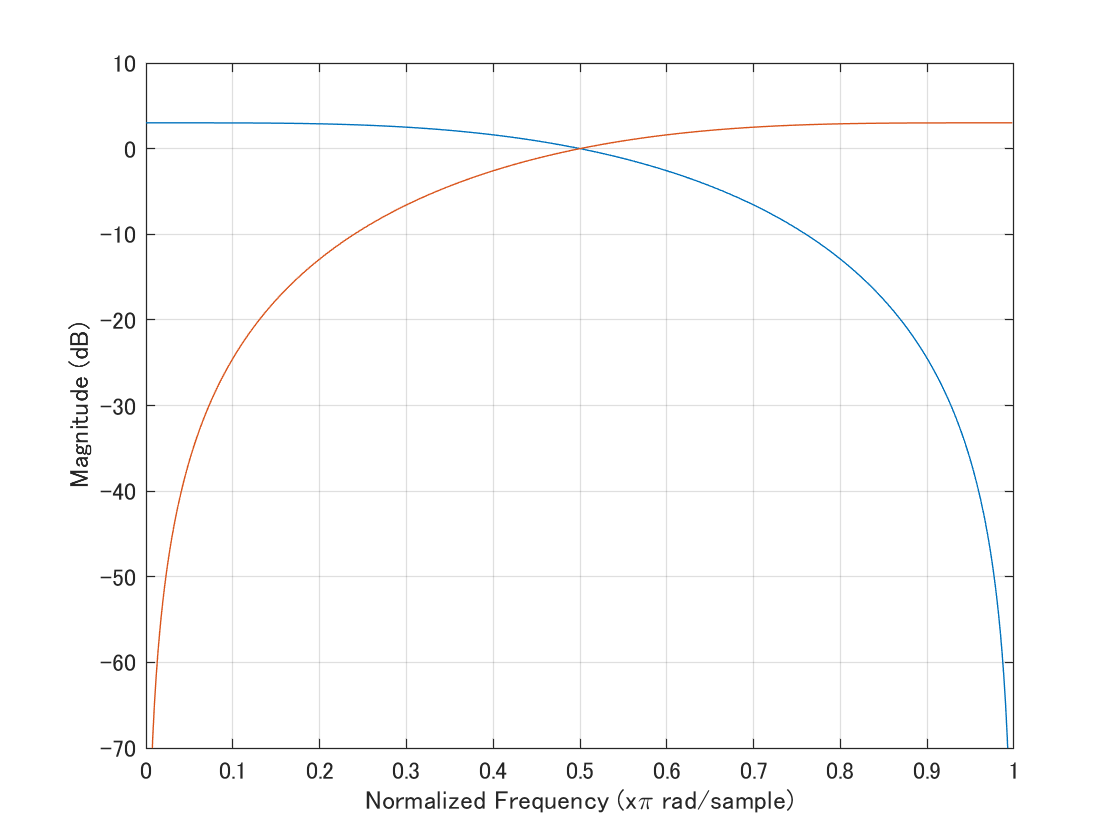

figure(3)
fftPoints = 512;
F = zeros(fftPoints,nChs);
% Low-pass filter
[F(:,1),W] = freqz(f0,1,fftPoints);
% High-pass filter
F(:,2)     = freqz(f1,1,fftPoints);
plot(W/pi,20*log10(abs(F)))
axis([0 1 -70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude (dB)')
grid on

### ポリフェーズ行列実装

(Polyphase matrix implemenation)

フィルタバンクをポリフェースフィルタに分解して、ポリフェーズ行列として実装

        
$$\mathbf{E}(z)=\left(\begin{array}{cc}  h_0[0] &h_0[1]\\ h_1[0]& h_1[1]\end{array}\right)
+\left(\begin{array}{cc}  h_0[2] &h_0[3]\\ h_1[2]& h_1[3]\end{array}\right)z^{-1}
=\left(\begin{array}{cc}  h_0[0]+h_0[2]z^{-1} &h_0[1]+h_0[3]z^{-1} \\ h_1[0]+h_1[2]z^{-1}& h_1[1]+h_1[3]z^{-1}\end{array}\right)$$


        
$$\mathbf{R}(z)=\left(\begin{array}{cc}  f_0[1] &f_1[1]\\ f_0[0]& f_1[0]\end{array}\right)
+\left(\begin{array}{cc}  f_0[3] &f_1[3]\\ f_0[2]& f_1[2]\end{array}\right)z^{-1}
=\left(\begin{array}{cc}  f_0[1]+f_0[3]z^{-1} &f_1[1]+f_1[3]z^{-1} \\ f_0[0]+f_0[2]z^{-1}& f_1[0]+f_1[2]z^{-1}\end{array}\right)$$


% Type-I polyphase filters of analyzer
e00 = h0(1:nChs:end);
e01 = h0(2:nChs:end);
e10 = h1(1:nChs:end);
e11 = h1(2:nChs:end);

% Type-II polyphase filters of synthesizer
r00 = f0(2:nChs:end);
r10 = f0(1:nChs:end);
r01 = f1(2:nChs:end);
r11 = f1(1:nChs:end);

分析合成処理 (Analysis and synthesis process)

% Input Signal
u = [zeros(1,nChs-1) u 0 ];
disp(u)

     0     0     3     1     3     1     5     3     0     0



% Serial/Pallalel conversion
u0 = downsample(u,nChs,0);
u1 = downsample(u,nChs,1);
x = [ u0 ; 
      u1 ];
disp(x)

     0     3     3     5     0
     0     1     1     3     0



% Analysis process w/ the polyphase matrix
% s = E*x
s0 = conv(e00,u0) + conv(e01,u1);
s1 = conv(e10,u0) + conv(e11,u1);
disp([s0;s1])

         0   -0.1641    2.8284    3.0179    5.6315         0
         0   -0.6124   -1.4142   -0.7071   -1.5089         0



% Synthesis process w/ the polyphase matrix
% v = R*s
v0 = conv(r00,s0) + conv(r01,s1);
v1 = conv(r10,s0) + conv(r11,s1);
disp([v0;v1])

         0    0.0000    3.0000    3.0000    5.0000    0.0000         0
         0    0.0000    1.0000    1.0000    3.0000         0         0



% Parallel/Serial conversion
v = upsample(u0,nChs,1)+upsample(u1,nChs,0);
disp(v)

     0     0     1     3     1     3     3     5     0     0



### ポリフェーズ行列実装（PPMATRIXオブジェクト利用）

(Polyphase matrix implemenation with PPMATRIX object)

ポリフェーズ行列演算が簡便となるよう以下のクラスを定義した。インスタンス化の際、3番目の添え字が遅延を示す3次元配列を渡す。

- PPMATRIX： Polyphase Matrix Class defined by Shogo MURAMATSU

分析合成処理 (Analysis and synthesis process)

import msip.ppmatrix
% Polyphase matrix of analysis bank
e00 = reshape(e00,1,1,length(e00));
e01 = reshape(e01,1,1,length(e01));
e10 = reshape(e10,1,1,length(e10));
e11 = reshape(e11,1,1,length(e11));
E = ppmatrix(cat(1,cat(2,e00,e01),cat(2,e10,e11)))

E = [
	-0.12941 + 0.83652*z^(-1),	0.22414 + 0.48296*z^(-1);
	-0.48296 - 0.22414*z^(-1),	0.83652 - 0.12941*z^(-1)
]


% Polyphase matrix of synthesis bank
r00 = reshape(r00,1,1,length(r00));
r10 = reshape(r10,1,1,length(r10));
r01 = reshape(r01,1,1,length(r01));
r11 = reshape(r11,1,1,length(r11));
R = ppmatrix(cat(1,cat(2,r00,r01),cat(2,r10,r11)))

R = [
	0.83652 - 0.12941*z^(-1),	-0.22414 - 0.48296*z^(-1);
	0.48296 + 0.22414*z^(-1),	-0.12941 + 0.83652*z^(-1)
]


% Confirmation of perfect reconstruction
disp(R*E)

[
	5.5511e-17 + 1*z^(-1) + 5.5511e-17*z^(-2),	0;
	0,	5.5511e-17 + 1*z^(-1) + 5.5511e-17*z^(-2)
]



% Define delaychain
clear delaychain
delaychain(1,1,2) = 1;
delaychain(2,1,1) = 1;
delaychain = ppmatrix(delaychain)

delaychain = [
	z^(-1);
	1
]


% Z-transform of input
u = ppmatrix(reshape(u,1,1,length(u)));
disp(u)

[
	3*z^(-2) + z^(-3) + 3*z^(-4) + z^(-5) + 5*z^(-6) + 3*z^(-7)
]



% Polyphase decomposition of input
x = downsample(delaychain*u,nChs);
disp(x)

[
	z^(-2) + z^(-3) + 3*z^(-4);
	3*z^(-1) + 3*z^(-2) + 5*z^(-3)
]



% Analysis process w/ the polyphase matrix
s = E*x;
disp(s)

[
	0.67243*z^(-1) + 1.9919*z^(-2) + 3.2767*z^(-3) + 2.8631*z^(-4) + 2.5095*z^(-5);
	2.5095*z^(-1) + 1.6384*z^(-2) + 3.0872*z^(-3) - 2.3201*z^(-4) - 0.67243*z^(-5)
]



% Synthesis process w/ the polyphase matrix
y = R*s;
disp(y)

[
	z^(-3) + 1*z^(-4) + 3*z^(-5) + 1.6653e-16*z^(-6);
	1.6653e-16*z^(-1) + 3*z^(-2) + 3*z^(-3) + 5*z^(-4) + 2.2204e-16*z^(-5)
]



% Parallel/Serial conversion
v = fliplr(delaychain.')*upsample(y,nChs);
disp(v)

[
	1.6653e-16*z^(-3) + 3*z^(-5) + z^(-6) + 3*z^(-7) + 1*z^(-8) + 5*z^(-9) + 3*z^(-10) + 2.2204e-16*z^(-11) + 1.6653e-16*z^(-12)
]



disp(squeeze(double(v)).')

         0         0         0    0.0000         0    3.0000    1.0000    3.0000    1.0000    5.0000    3.0000    0.0000    0.0000         0         0         0



© Copyright, Shogo MURAMATSU, All rights reserved.